# Safety Critical System, Week 9: Introduction to Fault and Disturbance

### A quick review

- Redundancy is a prerequisite of fault-tolerance control. For example, we need 2 valves or 2 sensors so that one can back up the other (**physical redundancy**), or a mathematical model of a valve so that we can estimate its true behavior if fault occurs (**analytical redundancy**).

- Disturbance should always be rejected by a controller, whereas it might not be possible to do so with faults.

Using an example of a two-tank system. Run this week assignment using model `assignment_0_2.slx` and view the results with `view.mldatx`

### Exercise 0: design an LQI controller when all of three actuators work normally

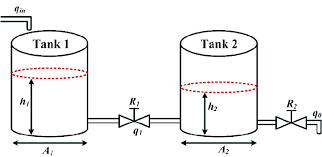

*Control inputs:*

- 
$$u_1~\text{(l/s): flow rate into tank 1}$$


- 
$$u_2~\text{(l/s): flow rate into tank 2}$$


- 
$$u_3~\text{(l/s): flow rate out of tank 2
}$$


*Controlled outputs:*

- 
$$h_1~(dm) \text{: water level in tank 1}$$


- 
$$h_2~(dm) \text{: water level in tank 2}$$


*Parameters:*

- 
$$R_i = \frac{1}{u_i}~\text{(s/l): resistance of valve i$$


- 
$$A_1 =1~(dm^2)\text{: bottom area of tank 1}$$


- 
$$A_2 = 2~(dm^2)\text{: bottom area of tank 2$$


- 
$$h_1(0) = h_2(0) = 0~(dm) \text{: initial heights of both tanks}$$


According to the lecture, we can derive both tanks' dynamical equations:


$$\begin{cases}
    \dot{h}_1 = -\frac{1}{R_2A_1}h_1 + \frac{1}{A_1}u_1 \\
    \dot{h}_2 = \frac{1}{R_2A_2}h_1 - \frac{1}{R_3A_2}h_2
\end{cases}

\Leftrightarrow

\begin{cases}
    \dot{h}_1 = -u_2h_1+u_1 \\
    \dot{h}_2 = \frac{u_2h_1}{2} - \frac{u_3h_2}{2}
\end{cases} \space (\textbf{*})$$


Linearize around the equilibrium point, we get an equivalent state space

- 
$$u_1^* = u_2^* = u_3^* = 0.5~(l/s)$$


- 
$$h_1^* = h_2^* = h(0) = 1~(dm)$$



$$(\textbf{*}) \Leftrightarrow
\begin{cases}
    \pmatrix{\delta \dot{h}_1 \cr \delta \dot{h}_2}
        = \pmatrix{-0.5 & 0 \cr 0.25 & 0.25} \pmatrix{\delta h_1 \cr \delta h_2}
            + \pmatrix{1 & -1 & 0 \cr 0 & 0.5 & -0/5} \pmatrix{\delta u_1 \cr \delta u_2 \cr \delta u_3}
    \\
    \pmatrix{\delta h_1 \cr \delta h_2} = \pmatrix{1 & 0 \cr 0 & 1} \pmatrix{\delta h_1 \cr \delta h_2}
\end{cases}$$


h0 = [0;0]; % Initial state as given above
r = [1;1]; % Ensure the system is always in the linear zone
A = [-0.5 0; 0.25 0.25];
B = [1 -1 0; 0 0.5 -0.5];
C = eye(2);
D = zeros(2,3);
plant = ss(A, B, C, D)

plant =
 
  A = 
         x1    x2
   x1  -0.5     0
   x2  0.25  0.25
 
  B = 
         u1    u2    u3
   x1     1    -1     0
   x2     0   0.5  -0.5
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.



% LQI parameters
Q = [1/0.1^2 0 0 0;...
     0 1/0.1^2 0 0;...
     0 0 1/0.1^2 0;...
     0 0 0 1/0.1^2];
R = [1/1^2 0 0;...
     0 1/0.2^2 0;...
     0 0 1/0.25^2];
[K, S, e] = lqi(plant, Q, R)

K =    10.3623    3.2563   -9.6640   -2.0559
   -0.3494    1.9615    0.4957   -1.1719
   -0.1018   -3.2684   -0.1705    1.9596


S =    10.3623    3.2563   -9.6640   -2.0559
    3.2563  104.5879    5.4561  -62.7067
   -9.6640    5.4561  110.3885   -0.3900
   -2.0559  -62.7067   -0.3900  150.9596


e =   -1.0039 + 0.0000i
  -1.2064 + 0.3648i
  -1.2064 - 0.3648i
 -10.1598 + 0.0000i


### Exercise 1: when valve 1 is broken

In other words, $\delta u_2 = 0$

B = [1 0; 0 -0.5];
D = zeros(2,2);
R = [1/1^2 0;...
     0 1/0.2^2];
plant = ss(A, B, C, D)

plant =
 
  A = 
         x1    x2
   x1  -0.5     0
   x2  0.25  0.25
 
  B = 
         u1    u2
   x1     1     0
   x2     0  -0.5
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


[K, S, e] = lqi(plant, Q, R)

K =    10.5098    2.6623   -9.8528   -1.7094
   -0.0532   -3.9422   -0.3419    1.9706


S =    10.5098    2.6623   -9.8528   -1.7094
    2.6623  197.1100   17.0937  -98.5282
   -9.8528   17.0937  112.2960   -3.1891
   -1.7094  -98.5282   -3.1891  174.1277


e =   -0.8840 + 0.4676i
  -0.8840 - 0.4676i
  -1.0041 + 0.0000i
  -9.9588 + 0.0000i


### Exercise 2: when valve 2 is broken

In other words, $\delta u_3 = 0$

B = [1 -1; 0 0.5];
D = zeros(2,2);
R = [1/1^2 0;...
     0 1/0.2^2];
plant = ss(A, B, C, D)

plant =
 
  A = 
         x1    x2
   x1  -0.5     0
   x2  0.25  0.25
 
  B = 
        u1   u2
   x1    1   -1
   x2    0  0.5
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


[K, S, e] = lqi(plant, Q, R)

K =    10.4571    6.2687   -9.4090   -3.3870
   -0.2929    3.8163    0.6774   -1.8818


S =    10.4571    6.2687   -9.4090   -3.3870
    6.2687  203.3533   15.0519 -100.8635
   -9.4090   15.0519  111.8179   -1.8843
   -3.3870 -100.8635   -1.8843  175.5538


e =   -0.8722 + 0.4688i
  -0.8722 - 0.4688i
  -1.0039 + 0.0000i
 -10.1599 + 0.0000i


### Exercise 3: when both valves are not available

In other words, $\delta u_2 = \delta u_3 = 0$. This task belongs to week 12, after we learn about "controller restructuring."